%%Example for PCA
%PCA uses singular value decomposition (svd) to find scores and loadings
%Define GC data as x
X = table2array(GCData(:,2))

X =    0.015901089345525   0.015598027890984   0.015779053433664   0.015917494043260   0.015974890696795   0.015553187064605   0.015438720268406   0.015559370982630   0.014819428087501   0.015039605251976   0.014888213044470   0.014623323679110   0.014810107686254   0.014613191947819   0.014899977330119   0.014681175469012   0.014966664702095   0.014788785536906   0.014711352988972   0.014783788931142   0.015170565794330   0.014588169341925   0.015036528134367   0.014963221496539   0.014567223174793   0.014778475708776   0.015047768023768   0.014808623545928   0.015223727700802   0.014608155764980   0.014603386727400   0.015040752987162   0.014900491832099   0.014746764577147   0.015683148285806   0.015227309426122   0.014928136419235   0.015346673885397   0.015046719231272   0.015510216255037   0.015384183058565   0.015407711629865   0.015439264453192   0.015077975226534   0.014986057469019   0.015265986123014   0.015266906290016   0.015180420486094   0.015263799489601   0.01511527662

%Scale the data
Xs=X*inv(diag(std(X)))

Xs =    9.794865634585236   9.444468189322762   9.461987680490816   9.777788357069941  10.446708303701200   9.701574639305607  10.380312597670448  10.625658023284528  10.506893393477004  10.313440223326214  10.681939003122000  10.197207023168335  10.561815348032175  10.716956687125856  11.179400719535664  10.624682751999092  10.874174675126508  10.809854093685287  10.859913213276853  10.418506905828693  11.196304748459347  10.706588450476138  10.757776763557732  10.856370839487122   9.923367467349260  10.493269932138309  10.935067535450269  10.436540699222892  11.083689256094170  11.080698414613735  10.338932831837852  10.331597091725479  10.657348576144066  10.640850906546186  11.419676775157095  10.727666893153538  10.591106385209731  10.861862374726792  10.523030351709181  10.941821435920854  10.816063020924714  10.535687670413706  10.222354578195400  10.385184213665507   9.882750582883968  10.602670040676454  10.405879606243797  10.579745426590732  10.010678824129405  10.8046381505

%Scores loadings
[U,D,Loadings]=svd(Xs)

U =   -0.143410305032746  -0.064392250462581  -0.111593615354291   0.178254959735191  -0.009265670108172   0.122025992726980  -0.174511016440620   0.088675432407216  -0.235936398296426   0.055300353608747  -0.154071428098753   0.055019606832139  -0.010222744595855   0.049785179310383   0.005742417161737  -0.405550645649759   0.005049531318109   0.030395532585535   0.023128284125675   0.041411523930290  -0.309926484362241  -0.084950786649394   0.224997182585483   0.036334063976135   0.004105409912931   0.032564553588080   0.416744528181169  -0.021671358186280  -0.276190201775876  -0.275968734174320   0.132175366863919   0.159083747675918   0.120713467296749   0.112835596907311  -0.088312243326089  -0.053685759625280  -0.025887977570914  -0.006872342778554  -0.081484812203244  -0.075893393678894   0.061655139911399   0.072161874917734  -0.189727661894144  -0.015063849542947
  -0.149300950043831  -0.052950217999577  -0.071675080016336  -0.031417980543517  -0.037953432415512   0.0274640466

D = 	1.0e+03 *

   3.440811063953386                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0    

Loadings =   -0.021078841064545  -0.015718278698186   0.006556337488095   0.004449208637564  -0.001112996258364  -0.003511252027773  -0.007208774999737  -0.020199901096317   0.022337676529363   0.020434742303990   0.019305010298667  -0.007783384701715   0.008083585695519  -0.009399021394850  -0.009076374741496   0.006347014791213   0.016365244755609   0.048676834021627   0.026191118419848   0.002976129437088   0.030658670352321   0.042535655647974  -0.032292835336482   0.005790655391914   0.020342112715066  -0.002652313421083   0.006546759855173   0.000037883648659   0.007092170514322  -0.002544555239959  -0.007678158278326   0.030548523575357   0.013319195760776  -0.029203545494763  -0.007078380931935  -0.051472207642281  -0.057570015383705  -0.013053941488553   0.022923934686247   0.046912614096254  -0.007362250645296  -0.024544482052079  -0.016869693279667   0.023294360892803  -0.016576323814609  -0.017476905907585  -0.019266911729798  -0.020131488201358  -0.021550497023302  -0.0192

Scores = U*D

Scores = 	1.0e+02 *

  -4.934477642416023  -0.052849162260751  -0.074565801155610   0.115279168467930  -0.005594690287605   0.063466359560658  -0.082576951984210   0.038135284320117  -0.087295822199858   0.018821348056502  -0.051210091993302   0.017846509174188  -0.003048982137237   0.013579231317297   0.001543874888577  -0.105813350813232   0.001266008580423   0.007142624161948   0.005304472035122   0.009135207408199  -0.066933950284878  -0.017682318960496   0.044364889038094   0.006799423580612   0.000750275970907   0.005568266731653   0.070734831804235  -0.003652598144458  -0.045611396308544  -0.045295956846804   0.020612364083309   0.024292809113175   0.018171235174666   0.015903052447296  -0.012198713877686  -0.007206933476457  -0.003398450599876  -0.000877576421394  -0.010381596812438  -0.009223478629041   0.007134151333966   0.008146732262480  -0.020429305395106  -0.001554227330841                   0                   0                   0                   0                   

%This line of code joins the label of the wine to the score values
Scores = [{Label_Wine_samples}, {Scores}]

Scores = 1×2 cell array
    {44×1 categorical}    {44×2700 double}


%Obtain the score values for the Argentinian wines
ARG=Scores{:,2}(Scores{:,1}=='ARG',2:3)

ARG =   -5.284916226075150  -7.456580115560951
  -4.345825223841084  -4.789261238057928
 -10.223154745849923   0.035714770214677
  -7.795199806959139  -3.112863370146698
   0.415577146278517  -9.381367950857614
   1.739470971781510   4.909844237244053


scatter(ARG(:,1),ARG(:,2),'red')
hold on 
AUS=Scores{:,2}(Scores{:,1}=='AUS',2:3)

AUS =    5.060651821330437  14.289263446474845
  -6.842670533273431  -9.498711452069003
  -3.866571630450863  -7.366813310981882
  15.837646772964888  16.456325687165343
   6.373377487357584  36.926157286572412
   3.845133658472617  -4.353337047875304
   7.619601286817498  -8.643889941842440
  -6.575352921843226   1.712631007924001
  -7.838435790304241  -6.071666343420956
  -0.213108722231449  -1.389241587644301


scatter(AUS(:,1),AUS(:,2),'black')
hold on
CHI=Scores{:,2}(Scores{:,1}=='CHI',2:3)

CHI =   -5.615681677503819   0.754275561332485
  -4.112455351554022  -8.748064696138387
   4.536065392187465  13.725117059831602
  -2.305195553356274   5.379431921816608
  -3.348401948657037  -8.155945305422765
   5.712875017894186  12.560911024982397
   0.861096270988999   9.849121137512558
  -4.504585628105781  -5.264138557331050
 -14.678651618786089  -6.213260517156592
  -3.368237094223421  -1.190651022984229


scatter(CHI(:,1),CHI(:,2),'blue')
hold on
SOU=Scores{:,2}(Scores{:,1}=='SOU',2:3)

SOU =    6.709632926959386  18.694356514739198
   5.660455124664888   0.383688876673039
  -6.159024979595906  -2.163963468805949
   1.218792055110982  -1.015177054623717
  -2.972716702049942   1.604102149813907
  -7.282037813394010  -4.171607113663995
  -4.511694080332392  -3.186647949763570
   5.399414861108987   4.940264851911559
  69.026082720004496 -23.416260296128957
  -1.593893498380714  -6.075541481571050


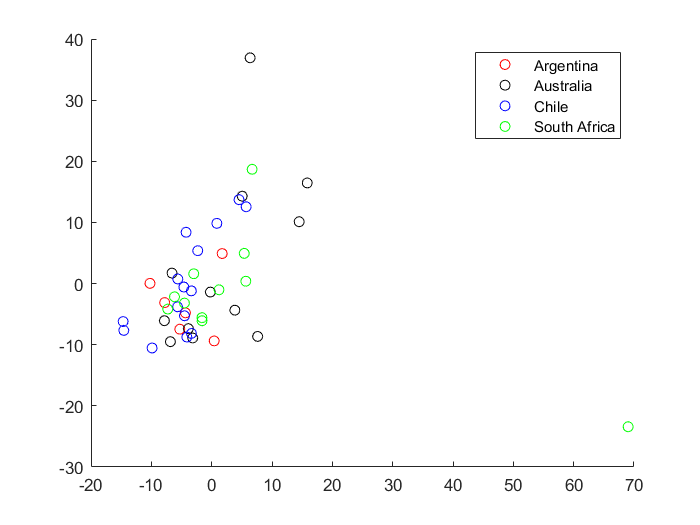

scatter(SOU(:,1),SOU(:,2),'green')
legend({'Argentina';'Australia';'Chile';'South Africa'})
hold off